# 实验二、数字PID控制

Ts=0.01;
Tf=0;

## 系统一

定义被控对象并进行离散化

Gp1=tf(5,conv([0.5 1],[0.1 1]));
Gp1d=c2d(Gp1,Ts,'zoh');

计算闭环传递函数

names={'原PID参数下','增大Kp','增大KI','增大KD'};
Gc=pid(1,0.02,1,Tf,Ts);
Phi1=feedback(series(Gc,Gp1d),1);
%增大比例环节
Gc=pid(1.2,0.02,1,Tf,Ts);
Phi2=feedback(series(Gc,Gp1d),1);
%增大积分环节
Gc=pid(1,0.12,1,Tf,Ts);
Phi3=feedback(series(Gc,Gp1d),1);
%增大微分环节
Gc=pid(1,0.02,2,Tf,Ts);
Phi4=feedback(series(Gc,Gp1d),1);

绘制系统一在不同PID参数下的阶跃响应

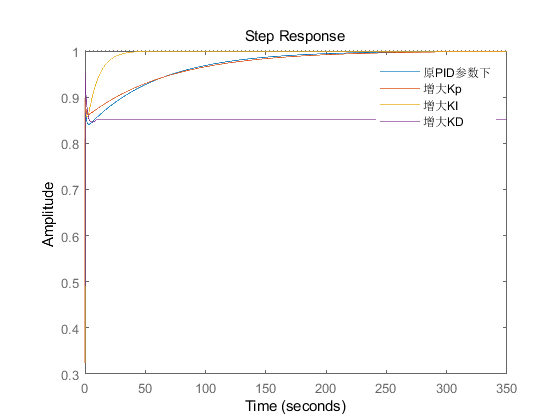

step(Phi1,Phi2,Phi3,Phi4);
legend(names);

计算阶跃相应的性能指标

s=[stepinfo(Phi1);stepinfo(Phi2);stepinfo(Phi3);stepinfo(Phi4)];
info=struct2table(orderfields(s,[5,2,1,3,4,7,8,6]),'RowNames',names');
display(info);

info = 4×8 table
                  Overshoot    SettlingTime    RiseTime    SettlingMin    SettlingMax     Peak      PeakTime    Undershoot
                  _________    ____________    ________    ___________    ___________    _______    ________    __________

    原PID参数下          0         149.66        54.62        0.93247        0.99874      0.99874     289.89         0     
    增大Kp              0         164.19        52.83        0.93246        0.99939      0.99939     378.99         0     
    增大KI              0          23.97         9.55        0.93249        0.99937      0.99937      51.39         0     
    增大KD         11.989           2.87            0        0.84601        0.95258      0.95258       0.01         0     


## 系统二

绘制系统二在不同PID参数下的阶跃响应

Gp2=tf(1,conv([1 0],[0.1 1]));
Gp2d=c2d(Gp2,Ts,'zoh');

计算闭环传递函数

names={'原PID参数下','增大Kp','增大KI','增大KD'};
Gc=pid(1,0.02,1,Tf,Ts);
Ph1=feedback(series(Gc,Gp2d),1);
%增大比例环节
Gc=pid(1.2,0.02,1,Tf,Ts);
Ph2=feedback(series(Gc,Gp2d),1);
%增大积分环节
Gc=pid(1,0.12,1,Tf,Ts);
Ph3=feedback(series(Gc,Gp2d),1);
%增大微分环节
Gc=pid(1,0.02,2,Tf,Ts);
Ph4=feedback(series(Gc,Gp2d),1);

绘制系统一在不同PID参数下的阶跃响应

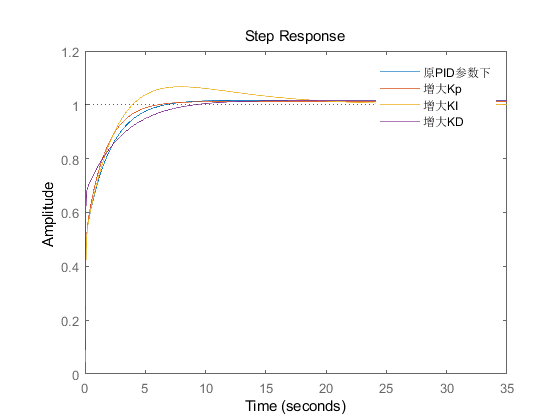

step(Ph1,Ph2,Ph3,Ph4);
legend(names);

计算阶跃相应的性能指标

s2=[stepinfo(Ph1);stepinfo(Ph2);stepinfo(Ph3);stepinfo(Ph4)];
info=struct2table(orderfields(s2,[5,2,1,3,4,7,8,6]),'RowNames',names')

info = 4×8 table
                  Overshoot    SettlingTime    RiseTime    SettlingMin    SettlingMax     Peak     PeakTime    Undershoot
                  _________    ____________    ________    ___________    ___________    ______    ________    __________

    原PID参数下     1.6471          5.25          3.03         0.9051        1.0165       1.0165     13.34          0     
    增大Kp         1.1952          4.56          2.55         0.9052         1.012        1.012     12.09          0     
    增大KI          6.714         18.29          2.49        0.90541        1.0671       1.0671      7.92          0     
    增大KD          1.545          6.96          3.58        0.90882        1.0155       1.0155     18.21          0     
